clear all;
close all;
set(0,'DefaultFigureWindowStyle','docked')

Nominal

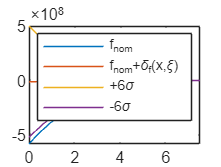

load opt.mat x L E Nelem r r_opt

[mean,sigma] = Perturbation(r, x, L, E, Nelem);
[r_in,r_out] = ExtractRadii(r);
Iyy = CalcSecondMomentAnnulus(r_in, r_out);

u = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
s = CalcBeamStress(L, E, r_out, u, Nelem);

figure(Name="Nominal")
plot(x,s)
hold on
plot(x,mean)
plot(x,mean+6*sigma)
plot(x,mean-6*sigma)
legend('f_{nom}','f_{nom}+\delta_{f}(x,\xi)','+6\sigma','-6\sigma')
hold off

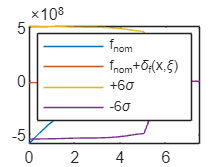


[mean,sigma] = Perturbation(r_opt, x, L, E, Nelem);
[r_in,r_out] = ExtractRadii(r);
Iyy = CalcSecondMomentAnnulus(r_in, r_out);

u = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
s = CalcBeamStress(L, E, r_out, u, Nelem);
figure(Name="Optimized")
plot(x,s)
hold on
plot(x,mean)
plot(x,mean+6*sigma)
plot(x,mean-6*sigma)
legend('f_{nom}','f_{nom}+\delta_{f}(x,\xi)','+6\sigma','-6\sigma')
hold off

load opt2.mat x L E Nelem r0 ropt
r = r0

r =       0.04625
      0.04625
      0.04625
      0.04625
      0.04625
      0.04625
      0.04625
      0.04625
      0.04625
      0.04625


r_opt = ropt

r_opt =      0.046377
     0.046766
      0.04712
     0.047446
     0.045286
     0.042655
     0.040077
     0.037551
      0.03508
     0.032663


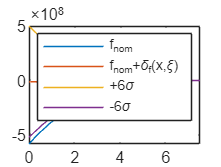


[mean,sigma] = Perturbation(r, x, L, E, Nelem);
[r_in,r_out] = ExtractRadii(r);
Iyy = CalcSecondMomentAnnulus(r_in, r_out);

u = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
s = CalcBeamStress(L, E, r_out, u, Nelem);

figure(Name="Nominal")
plot(x,s)
hold on
plot(x,mean)
plot(x,mean+6*sigma)
plot(x,mean-6*sigma)
legend('f_{nom}','f_{nom}+\delta_{f}(x,\xi)','+6\sigma','-6\sigma')
hold off

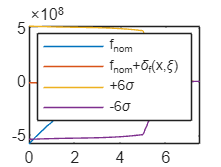


[mean,sigma] = Perturbation(r_opt, x, L, E, Nelem);
[r_in,r_out] = ExtractRadii(r);
Iyy = CalcSecondMomentAnnulus(r_in, r_out);

u = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
s = CalcBeamStress(L, E, r_out, u, Nelem);
figure(Name="Optimized")
plot(x,s)
hold on
plot(x,mean)
plot(x,mean+6*sigma)
plot(x,mean-6*sigma)
legend('f_{nom}','f_{nom}+\delta_{f}(x,\xi)','+6\sigma','-6\sigma')
hold off